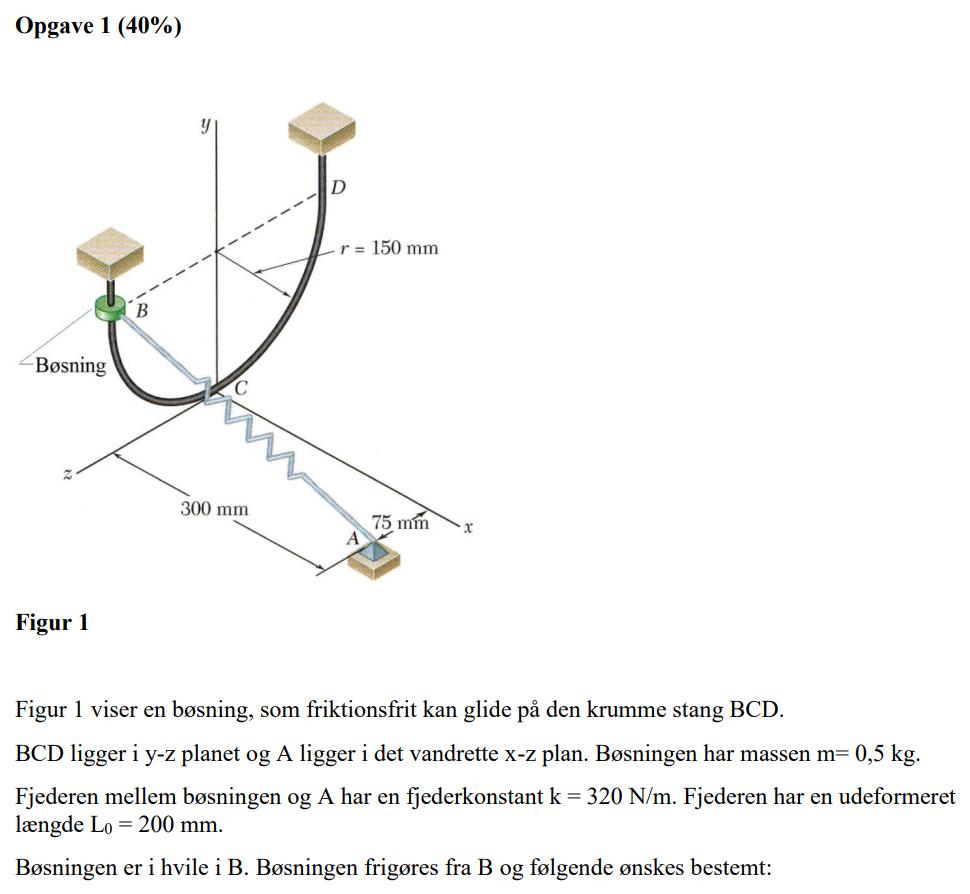

## A) Vis at fjerdenrs totale længde $L_{AC}$, mellem A & C er lig med 309,23 mm og fjederens totale længde $L_{AB}$ mellem A og B er lig med 343.69 mm.

Til den første del af dette spørgsmål Fjerderens totale længde $L_{AC}$ = 309.23 mm vil pytagoras anvendes:

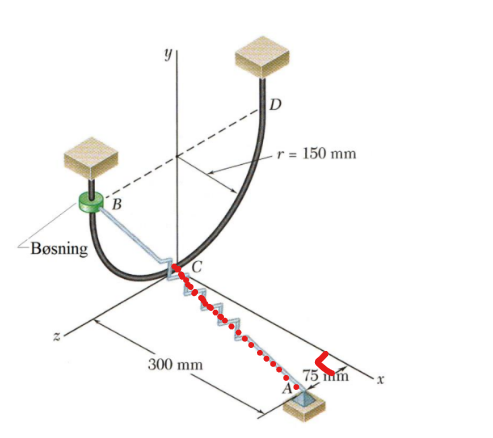

- 
$$L_{AC} = \sqrt{ L_{a}^2 + L_{c}^2 } \rightarrow \sqrt{ (75 mm)^2 + (300 mm)^2 } = 309.233 mm$$


L_A = 75;
L_C = 300;
r = 150;
L_AC = sqrt(L_A^2 + L_C^2)

L_AC = 309.2329

Den anden længde $L_{AB}$ kan også finde gennem pythagoras. 

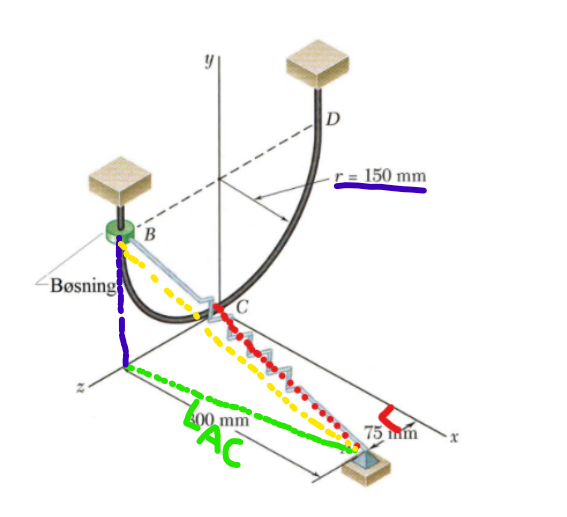

L_AB = sqrt(L_AC^2 + r^2)

L_AB = 343.6932


$$L_{AB} = \sqrt{ L_{AC}^2 + r^2 } \rightarrow \sqrt{ (309.233 mm)^2 + (150 mm)^2 } = 343.692 mm$$


## B) Bøsningens hastighed $v_C$ når den passerer C.

Da bøsningen er sluppet fra hvivle, så kan vi anvende følgende formel til at finde bøsningens hastighed:

- 
$$s = \frac{v_c^2 - v_0^2}{2 \cdot a} \rightarrow v_c = \sqrt{\frac{2 \cdot 0.15 m \cdot \pi}{4} \cdot 2 \cdot 9.81\frac{m}{s^2}} = 2.15 \frac{m}{s}$$


g = 9.81;
v_c = sqrt(2*g*((2*(r/1000)*pi)/4))

v_c = 2.1501

## C) Kraften F, som stangen påvirker bøsningen med i C.

Da stangen er ophængt, så er den eneste kraft som stangen kan påvirke bøsningen med normalkraften, der er påvirker af fjerderen og bøsningens vægtbidrag.

Angivet er fjederens equilibrium længde: 200mm.

Mellem A og C har fjerderen længden oplyst fra opgaven og regnet i underopgave A: $L_{AC} = 309.23 mm$

Dette vil sige, at den kraft, som fjederen trækker bøsningen med kan findes som:

- 
$$F = k \cdot (L_{AC} - L_0) \rightarrow 320 \cdot (0.30923 - 0.2) = 3.28 N$$


F = k * ((L_AC-200)/1000)

F = 3.2770

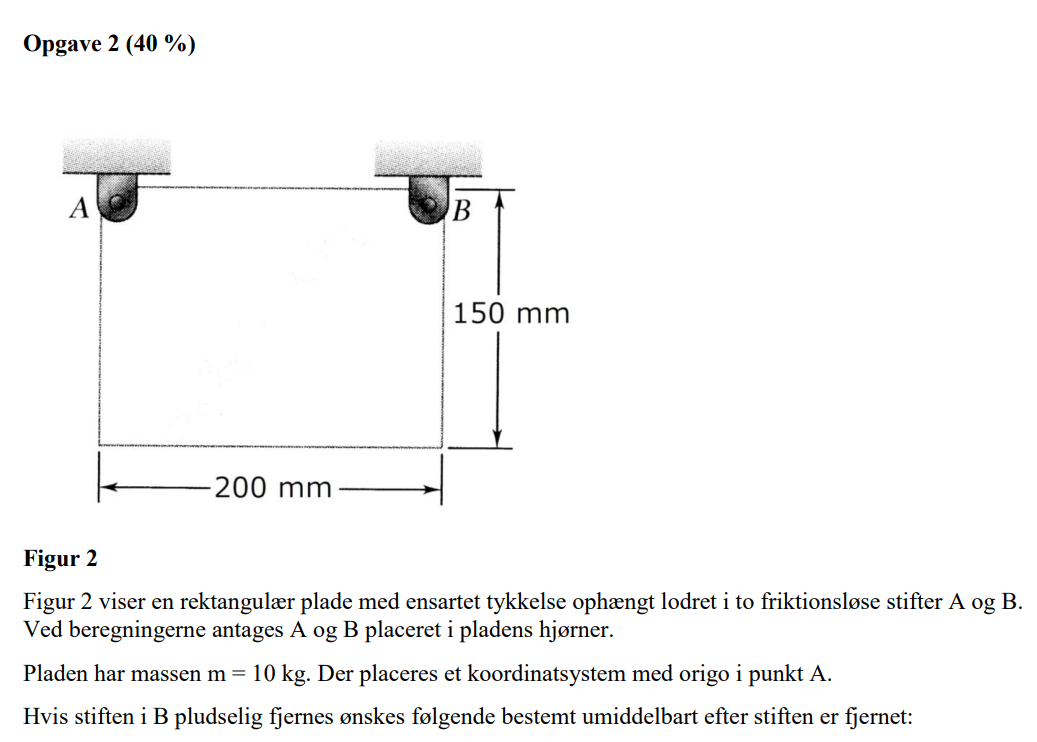

## A) Optegn frit legeme diagram (FBD) og kinetisk diagram (KD)

## B) Bestem pladens masseinertimoment om tyngdepunktet $I_G$

Da vores plade er en rektangel, så kan vi finde tyngdepunktet som værende en plade:

- 
$$I_G = \frac{1}{12} \cdot m \cdot (a^2 + b^2) \rightarrow \frac{1}{12} \cdot 10kg \cdot ((0.15m)^2 + (0.2m)^2) = 0.0521 kg \cdot m^2$$


m = 10;
a = 0.15;
b = 0.2;
g = 9.81;
I_G = (1/12) * m * (a^2 + b^2)

I_G = 0.0521

## C) Bestem pladens masseinertimoment $I_A$ om punkt A

Masseinertimomentet kan bestemmes gennem:

- 
$$I_A = I_G + m \cdot r^2 \rightarrow 0.0521 kg \cdot m^2 + 10 kg \cdot \sqrt{(0.075 m)^2 + (0.100 m)^2} = 0.2083 kg \cdot m^2$$


r = sqrt((a/2)^2 + (b/2)^2)

r = 0.1250

I_A = I_G + m * r^2

I_A = 0.2083

## D) Bestem pladens vinkelacceleration $\alpha$ – resultatet ønskes anført som $\alpha k$

Pladens vinkelacceleration kan findes gennem moment ligningen:

- 
$$\sum M_A = I_A \cdot \alpha : 10 kg \cdot 9.81\frac{m}{s^2} \cdot \frac{0.2m}{2} = 0.2083 kg \cdot m^2 \cdot \alpha

\rightarrow 

\alpha = \frac{10 kg \cdot 9.81\frac{m}{s^2} \cdot \frac{0.2m}{2}}{0.2083 kg \cdot m^2} = 47.088 k$$


alpha = (m*g*(b/2))/I_A

alpha = 47.0880

## E) Bestem reaktionskraften $F_A$ i A - anført som $F_{Ax}$ i og FAyj 

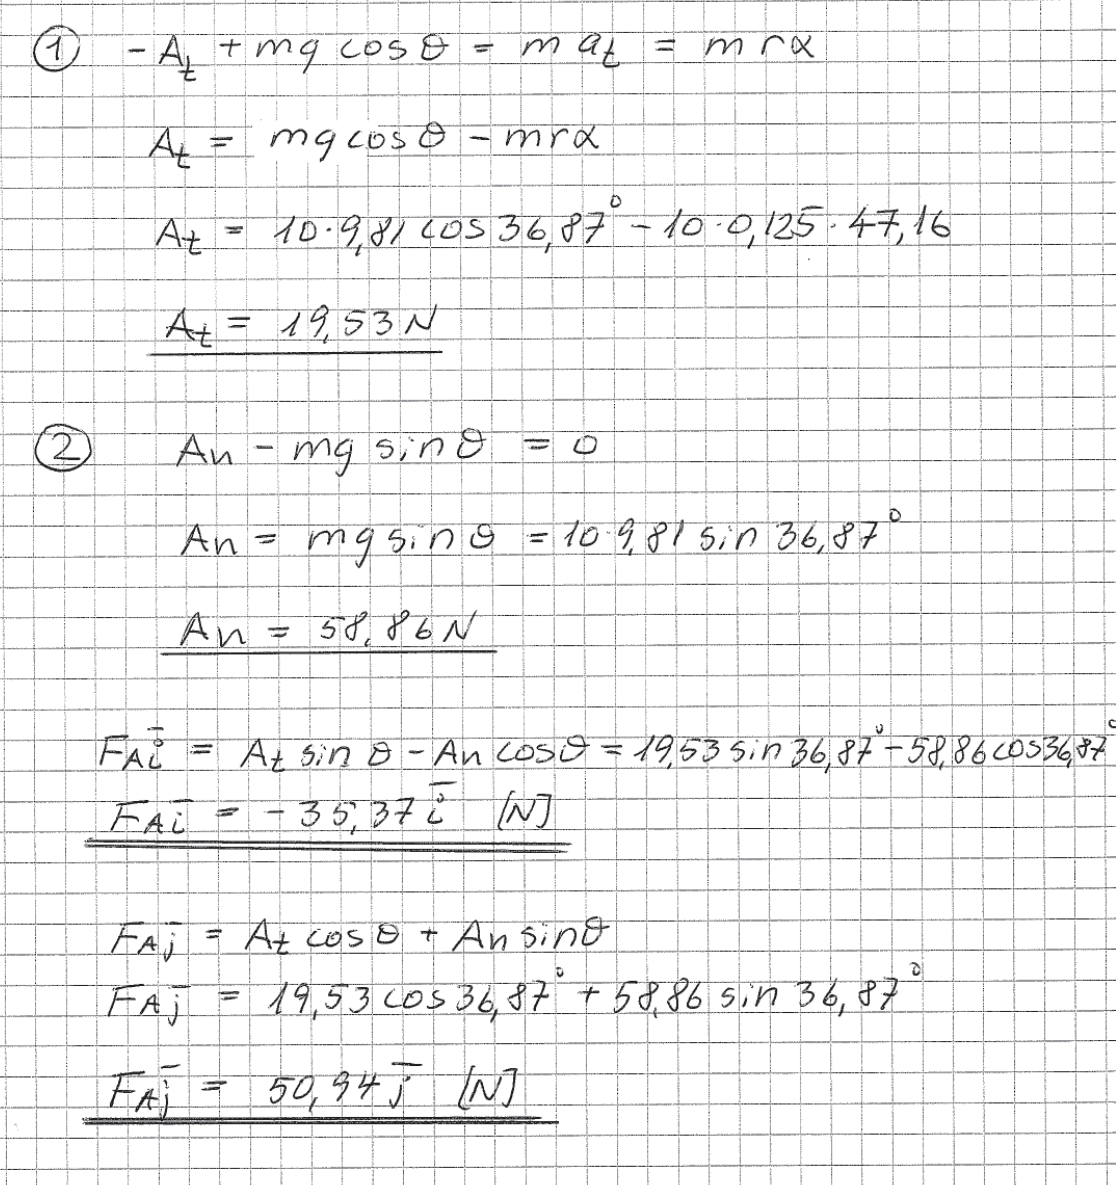

## 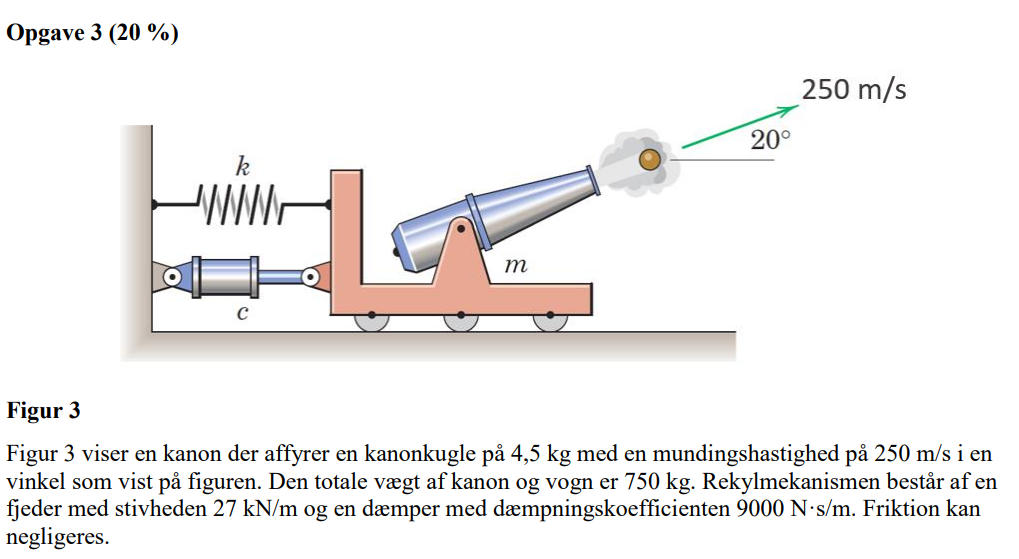

## A) Bestem kanonens vandrette hastighed lige efter affyring. Anvend bevarelse af lineær momentum.

Da vi skal anvende lineær momentum til udførslen af denne opgave får vi:

- 
$$\Delta G_x = m_1 \cdot v_1 = m_2 \cdot v_2 : 750 kg \cdot v_1 = 4.5kg \cdot (250 \frac{m}{s} \cdot cos(20\degree )  \rightarrow v_1 = \frac{4.5kg \cdot (250 \frac{m}{s} \cdot cos(20\degree )}{750kg} = 1.41 \frac{m}{s}$$


m = 750;
m_2 = 4.5;
v_2 = 250;
k = 27000;
c = 9000;

v = (m_2 * (v_2 * cosd(20)))/m

v = 1.4095

## B) Bestem systemets cykliske egenfrekvens og dæmpningsforholdet.

Egenfrekvensen og dæmpningsforholdet er respektivit angivet som:

- 
$$\omega_n = \sqrt{\frac{k}{m}} = \sqrt{\frac{27,000 \frac{N}{m}}{750kg}} = 6 \frac{rads}{s}$$


- 
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n} = \frac{9000 N \cdot \frac{s}{m}}{2 \cdot 750 kg \cdot 27,000 \frac{N}{m}} = 1$$


Heraf er det angivet at den cykliske egenfrekvens og dæmpningsforholdet er:

- Egenfrekvens: $6 \frac{rads}{s}$

- Dæmpningsforholdet = 1 $\equiv$ Kristik dæmpet system

omega_n = sqrt(k/m)

omega_n = 6

zeta = c/(2*m*omega_n)

zeta = 1

## C) Bestem kanonens største vandrette flytning.

Da systemet er kritisk er afstand og hastighedsligningerne:

- 
$$x(t) = (A + B\cdot t)\cdot e^{-\omega_n \cdot t}$$


- 
$$\dot{x}(t) = B \cdot e^{-\omega_n \cdot t} + (A + B \cdot t) \cdot -\omega_n \cdot e^{-\omega_n \cdot t}$$


Vi skal bestemme konstanterne A & B før vi kan finde den maksimale vandrette flytning baseret på den fundende hastighed fra opgave A:

syms A B t;
eq1 = (A + B * 0)*exp(-omega_n*0) == 0;
eq2 = B * exp(-omega_n*0) + (A + B * 0) * (-omega_n) * exp(-omega_n*0) == v;
eq3 = solve([eq1 eq2],[A B]);
eq3.A;
eq3.B;

x = vpa(eq3.B * exp(-omega_n*t) + (eq3.A + eq3.B * t) * (-omega_n) * exp(-omega_n*t),6)

$$x = 1.40954\,{\mathrm{e}}^{-6.0\,t}-8.45723\,t\,{\mathrm{e}}^{-6.0\,t}$$

tiden = solve(x,t)

$$tiden = 0.16666666666666666666666666666667$$

x_max = (eq3.A + eq3.B * tiden)*exp(-omega_n*tiden)

$$x\_max = 0.086423399051912000792879297301104$$

Hvorved den største flyning bliver: $x_{max} = 0.0864 m$